### Automatic generation of different shapes of nanoparticules with Gielis SuperFormula 

 
$$r\left(\varphi \right)={\left({\left(\frac{\cos \left(\frac{m\varphi }{4}\right)}{a}\right)}^{\textrm{n2}} +{\left(\frac{\sin \left(\frac{m\varphi }{4}\right)}{b}\right)}^{\textrm{n3}} \right)}^{\frac{-1}{\textrm{n1}}}$$


% mn = [m, n1, n2, n3]
%   [4 1 1 1] : Diamond
%   [4 2 2 2] : Circle or ellipse
%   [4 n n n] : n>2 rounded square or rectangle 
%   [3 n 2*n 2*n] : rounded triangle n>1
%   mn = 4 : Rectangle or square 

*Gielis, Johan (2003), *[*"A generic geometric transformation that unifies a wide range of natural and abstract shapes"*](https://bsapubs.onlinelibrary.wiley.com/doi/10.3732/ajb.90.3.333)*, *[*American Journal of Botany*](https://en.wikipedia.org/wiki/American_Journal_of_Botany)*, ****90**** (3): 333–338, *[*doi*](https://en.wikipedia.org/wiki/Doi_(identifier))*:*[*10.3732/ajb.90.3.333*](https://doi.org/10.3732%2Fajb.90.3.333)*, *[*ISSN*](https://en.wikipedia.org/wiki/ISSN_(identifier)) [*0002-9122*](https://www.worldcat.org/issn/0002-9122)*, *[*PMID*](https://en.wikipedia.org/wiki/PMID_(identifier)) [*21659124*](https://pubmed.ncbi.nlm.nih.gov/21659124)

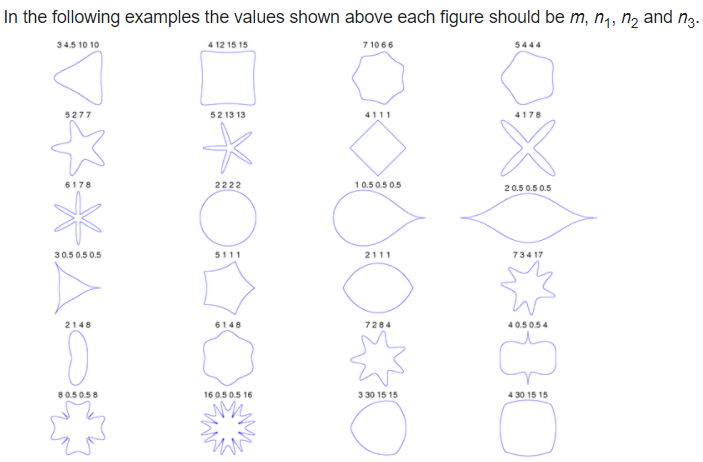

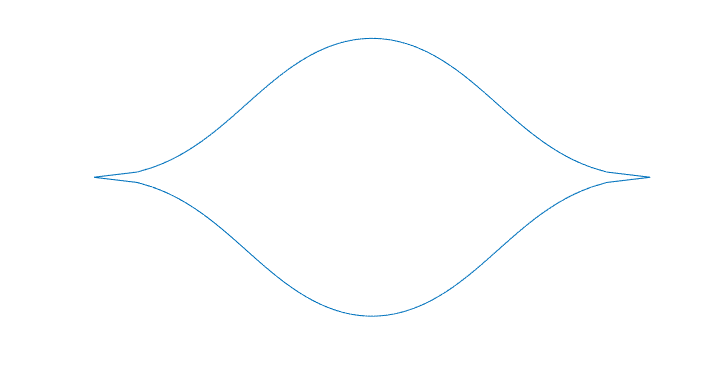

%   [xv,yv] = sf2d(nm, ab, Angle, Dep, Np);               
%
% Description
%   nm : List of parameters [m, n1, n2, n3]
%   ab : Radius [a b]
%   Angle : Angle of rotation (rd)
%   Dep   : Translation in x and y
%   Np     : Nomber of points (Np = 401 by default)
%
%   xv : Abscissa of points
%   yv : Ordonates of points

[xv,yv] = sf2d([2 .5 .5 .5],[2 1],0,[ 0 0],401);
%
figure('Position',[293  302  460  235]),
p = plot(xv,yv); axis equal, axis off 

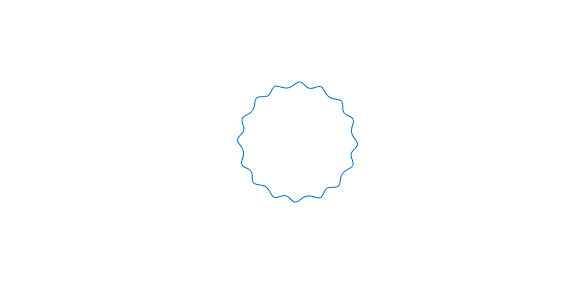


a = 4;
b = 4;
%
m =16;
n1 = 6.9;
n2 = 2.7; 
n3 = 5.3;
%
Angle = 100*pi/180;
%
[xv,yv] = sf2d([m n1 n2 n3], [a b],Angle,[ 0 0],401);
%

%
p.XDataSource = 'xv'; p.YDataSource = 'yv';
refreshdata
axis([-2*max(xv(:)) 2*max(xv(:)) -2*max(yv(:)) 2*max(yv(:))]), drawnow